close all;
clear all;
clc;

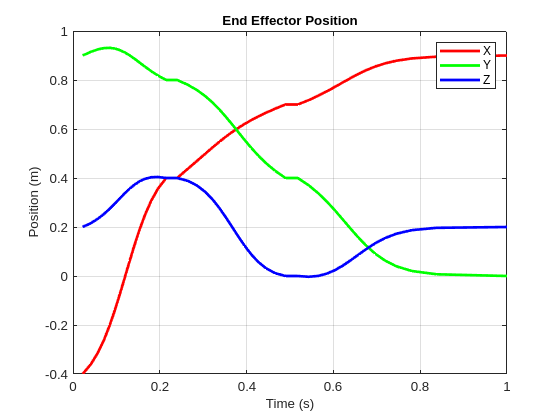

% Load UR5e robot
robot = loadrobot("universalUR5e");
robot.DataFormat = 'row';

% Add gripper (optional)
ur5e = exampleHelperAddGripper(robot);

% Home position
homePosition = deg2rad([-15, -126, 113, -80, -91, 76]);
for i = 1:6
    ur5e.Bodies{i+2}.Joint.HomePosition = homePosition(i);
end

% Inverse kinematics solver
ik = inverseKinematics('RigidBodyTree', ur5e);
weights = [1, 1, 1, 1, 1, 1];
initialGuess = homePosition;

% Define waypoints with 4 control points
waypoints = [-0.6, -0.4, 0.4, 0.7, 0.9, 0.8;  % X positions
             0.3, 0.9, 0.8, 0.4, 0.0, 0.3;  % Y positions
             0.0, 0.2, 0.4, 0.0, 0.2, 0.0]; % Z positions

% Transpose waypoints to match Catmull-Rom requirements
controlPoints = waypoints';

% Number of samples (interpolated points)
numSamples = 15;
interpolatedPoints = [];
velocities = [];
accelerations = [];

% Derive velocity and acceleration expressions for the spline
for i = 2:size(controlPoints, 1)-2
    P_prev = controlPoints(i-1, :);
    P_curr = controlPoints(i, :);
    P_next = controlPoints(i+1, :);
    P_next2 = controlPoints(i+2, :);
    
    for t = linspace(0, 1, numSamples)
        % Position (P(t)) - already implemented in your spline code
        C_x = 0.5 * ((-t^3 + 2*t^2 - t) * P_prev(1) + ...
                     (3*t^3 - 5*t^2 + 2) * P_curr(1) + ...
                     (-3*t^3 + 4*t^2 + t) * P_next(1) + ...
                     (t^3 - t^2) * P_next2(1));
                 
        C_y = 0.5 * ((-t^3 + 2*t^2 - t) * P_prev(2) + ...
                     (3*t^3 - 5*t^2 + 2) * P_curr(2) + ...
                     (-3*t^3 + 4*t^2 + t) * P_next(2) + ...
                     (t^3 - t^2) * P_next2(2));
                 
        C_z = 0.5 * ((-t^3 + 2*t^2 - t) * P_prev(3) + ...
                     (3*t^3 - 5*t^2 + 2) * P_curr(3) + ...
                     (-3*t^3 + 4*t^2 + t) * P_next(3) + ...
                     (t^3 - t^2) * P_next2(3));
                 
        % Compute velocity (1st derivative of position)
        V_x = 0.5 * (-3*t^2 + 4*t - 1) * P_prev(1) + ...
                     (9*t^2 - 10*t) * P_curr(1) + ...
                     (-9*t^2 + 8*t + 1) * P_next(1) + ...
                     (3*t^2 - 2*t) * P_next2(1);
                 
        V_y = 0.5 * (-3*t^2 + 4*t - 1) * P_prev(2) + ...
                     (9*t^2 - 10*t) * P_curr(2) + ...
                     (-9*t^2 + 8*t + 1) * P_next(2) + ...
                     (3*t^2 - 2*t) * P_next2(2);
                 
        V_z = 0.5 * (-3*t^2 + 4*t - 1) * P_prev(3) + ...
                     (9*t^2 - 10*t) * P_curr(3) + ...
                     (-9*t^2 + 8*t + 1) * P_next(3) + ...
                     (3*t^2 - 2*t) * P_next2(3);

        % Compute acceleration (2nd derivative of position)
        A_x = 0.5 * (-6*t + 4) * P_prev(1) + ...
                     (18*t - 10) * P_curr(1) + ...
                     (-18*t + 8) * P_next(1) + ...
                     (6*t - 2) * P_next2(1);
                 
        A_y = 0.5 * (-6*t + 4) * P_prev(2) + ...
                     (18*t - 10) * P_curr(2) + ...
                     (-18*t + 8) * P_next(2) + ...
                     (6*t - 2) * P_next2(2);
                 
        A_z = 0.5 * (-6*t + 4) * P_prev(3) + ...
                     (18*t - 10) * P_curr(3) + ...
                     (-18*t + 8) * P_next(3) + ...
                     (6*t - 2) * P_next2(3);

        % Store the position, velocity, and acceleration for plotting
        interpolatedPoints = [interpolatedPoints; C_x, C_y, C_z];
        velocities = [velocities; V_x, V_y, V_z];
        accelerations = [accelerations; A_x, A_y, A_z];
    end                                       
end

% velocity based Time vector 
velocities_magnitude = sqrt(velocities(:,1).^2 + velocities(:,2).^2 + velocities(:,3).^2);
time = cumsum(1 ./ velocities_magnitude);
time = time / max(time); % Normalize to [0,1]

% Position plot
figure;
plot(time, interpolatedPoints(:,1), 'r', 'LineWidth', 2); hold on;
plot(time, interpolatedPoints(:,2), 'g', 'LineWidth', 2);
plot(time, interpolatedPoints(:,3), 'b', 'LineWidth', 2);
title('End Effector Position','FontSize',10);
xlabel('Time (s)','FontSize',10);
ylabel('Position (m)','FontSize',10);
legend({'X', 'Y', 'Z'});
grid on;

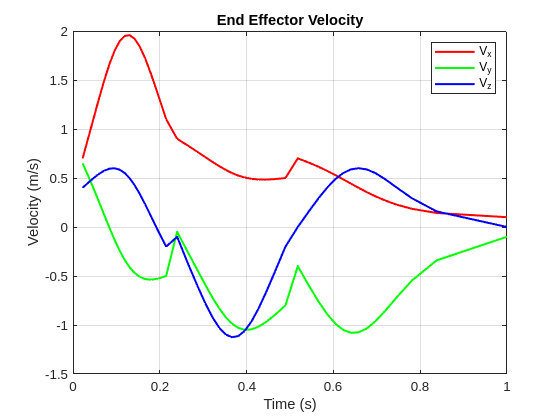


% Velocity plot (showing X, Y, Z components)
figure;
plot(time, velocities(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(time, velocities(:,2), 'g', 'LineWidth', 1.5);
plot(time, velocities(:,3), 'b', 'LineWidth', 1.5);
title('End Effector Velocity');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
legend({'V_x', 'V_y', 'V_z'});
grid on;

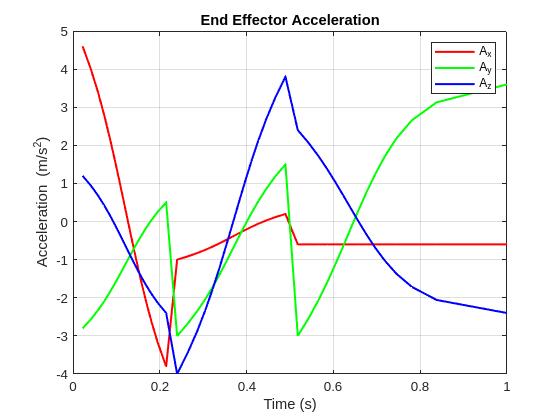


% Acceleration plot (showing X, Y, Z components)
figure;
plot(time, accelerations(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(time, accelerations(:,2), 'g', 'LineWidth', 1.5);
plot(time, accelerations(:,3), 'b', 'LineWidth', 1.5);
title('End Effector Acceleration');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
legend({'A_x', 'A_y', 'A_z'});
grid on;

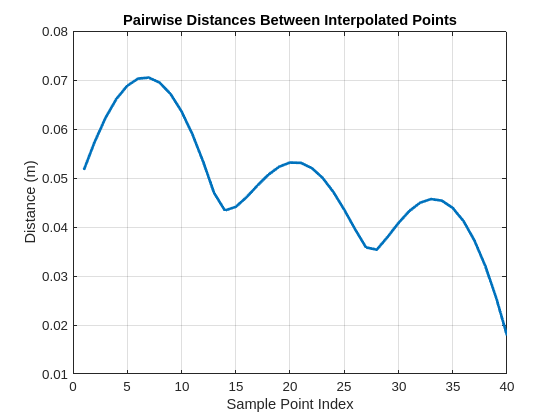

excludeControlPoints = false(size(interpolatedPoints, 1), 1);

for i = 1:size(controlPoints, 1)
    for j = 1:size(interpolatedPoints, 1)
        % Check if the interpolated point matches the control point
        if all(abs(interpolatedPoints(j,:) - controlPoints(i,:)) < 1e-6)
            excludeControlPoints(j) = true;  % Mark the control point to exclude
            break;
        end
    end
end

% Exclude the control points (waypoints) from the interpolated points
interpolatedPointsWithoutWaypoints = interpolatedPoints(~excludeControlPoints, :);

% Now compute pairwise distances for the remaining points (excluding control points)
distances = sqrt(sum(diff(interpolatedPointsWithoutWaypoints).^2, 2));

% Plot pairwise distances (excluding control points)
figure;
plot(1:length(distances), distances, 'LineWidth', 2);
title('Pairwise Distances Between Interpolated Points');
xlabel('Sample Point Index');
ylabel('Distance (m)');
grid on;

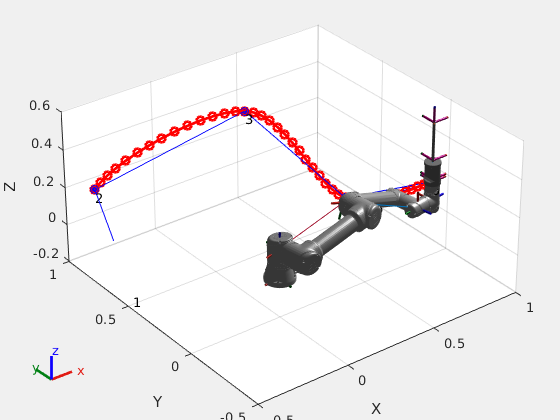

% Visualize the robot's path and waypoints
figure;
show(ur5e, homePosition, 'Frames', 'on', 'PreservePlot', true);
hold on;

% Plot interpolated trajectory
plot3(interpolatedPoints(:, 1), interpolatedPoints(:, 2), interpolatedPoints(:, 3), 'ro-', 'LineWidth', 2);

% Plot waypoints (control points)
plot3(waypoints(1,:), waypoints(2,:), waypoints(3,:), 'bo-', 'MarkerFaceColor', 'b');

% Add labels
text(waypoints(1,:), waypoints(2,:), waypoints(3,:), {'1','2','3','4','5','6'}, 'VerticalAlignment','top','HorizontalAlignment','left');

% Create a VideoWriter object
videoFilename = 'Catmull_rom_animation.avi'; % Output video file name
video = VideoWriter(videoFilename, 'Motion JPEG AVI'); % Choose format (can also be 'MPEG-4')
video.FrameRate = 30; % Set frames per second (FPS)
open(video); % Open the video file

% Set the initial camera angle and axis limits
view(3);  % Set the view to 3D
axis([-0.5 1 -0.5 1 -0.2 0.6]);  % Set axis limits for a clear view
grid on;
axis equal;

% Define dynamic Z axis limits
zMin = -0.2;
zMax = 0.6;

% Your existing code to animate the UR5e robot
for i = 1:size(interpolatedPoints, 1)
    targetPose = trvec2tform(interpolatedPoints(i, :)); % Convert to homogeneous transformation
    [configSol, solInfo] = ik("tool0", targetPose, weights, initialGuess);
    initialGuess = configSol;  % Update the initial guess
    
    % Display the robot configuration
    show(ur5e, configSol, 'PreservePlot', false);
    
    % Update Z axis dynamically based on the robot's current position
    currentZ = interpolatedPoints(i, 3); % Z-coordinate of the robot's end effector
    
    % Adjust Z limits slightly around the current position
    zMin = min(zMin, currentZ - 0.2); % Slight zoom-out in Z
    zMax = max(zMax, currentZ + 0.2); % Slight zoom-out in Z
    
    % Update axis limits dynamically
    axis([-0.5 1 -0.5 1 zMin zMax]);
    
    % Capture the current figure as a frame
    frame = getframe(gcf);  % Capture the frame from the current figure
    writeVideo(video, frame); % Write the captured frame to the video
    
    pause(0.01);  % Pause to control animation speed
end


% Close the video file after finishing the animation
close(video);

disp('Animation saved as Catmull_rom_animation.avi');

Animation saved as Catmull_rom_animation.avi
